clc; clear; close all; % Komut penceresini temizler, değişkenleri silmek ve grafikleri kapatmak için


x = input('x degerini giriniz: '); % Kullanıcıdan x değeri aldık
n = input('Terim sayisini (n) giriniz: '); % Taylor serisinde kullanılacak terim sayısını kullanıcadan aldık

taylor_sonuc = 0; % Başlangıçta toplam 0

for k = 0:n % 0'dan n'e kadar döngü 
    terim = (x^k) / factorial(k); % Taylor serisinin k. terimi hesapladık
    taylor_sonuc = taylor_sonuc + terim; % Terim toplam değere ekledik
end

gercek_sonuc = exp(x); % MATLAB'in exp fonksiyonu kullanılır (karşılaştırma için kullandım)


fprintf('Taylor sonucu: %.6f\n', taylor_sonuc); % Taylor sonucu yazdırdık

Taylor sonucu: 2.718282


fprintf('Gercek sonuc (exp): %.6f\n', gercek_sonuc); % Gerçek değer yazdırdık

Gercek sonuc (exp): 2.718282


fprintf('Hata: %.6f\n', abs(gercek_sonuc - taylor_sonuc)); % Hatayı yazdırdık

Hata: 0.000000


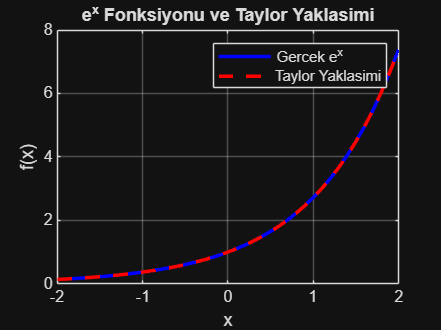


% Grafik için x değerleri oluşturuyrouz
x_grafik = -2:0.1:2; 

% Gerçek e^x eğrisi
gercek_grafik = exp(x_grafik); 

% Taylor yaklaşımı için dizi oluşturduk
taylor_grafik = zeros(size(x_grafik)); % Başlangıçta sıfır vektörü


for i = 1:length(x_grafik) % Tüm x değerleri için döngü
    toplam = 0; % Her x için toplam sıfırlanır
    for k = 0:n % Taylor terimleri
        toplam = toplam + (x_grafik(i)^k) / factorial(k); % Toplam hesapladık
    end
    taylor_grafik(i) = toplam; % Sonucu diziye atadık
end


figure; % Yeni grafik penceresi açar
plot(x_grafik, gercek_grafik, 'b', 'LineWidth', 2); % Gerçek eğri (mavi olan)
hold on; % Aynı grafikte çizim yapabilmek için
plot(x_grafik, taylor_grafik, 'r--', 'LineWidth', 2); % Taylor yaklaşımı (kırmızı kesikli)

xlabel('x'); % x ekseni etiketi
ylabel('f(x)'); % y ekseni etiketi
title('e^x Fonksiyonu ve Taylor Yaklasimi'); % Grafik başlığı
legend('Gercek e^x', 'Taylor Yaklasimi'); % Açıklama 
grid on; 